%2d potential model
gonchar(1:1000) = sqrt(1/(pi))

lineWid = 2;
lineSty='--';
lineCol= [ 0/255 114/255 178/255];
plot(t_dimless_0, gonchar(1:length(t_dimless_0)), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;


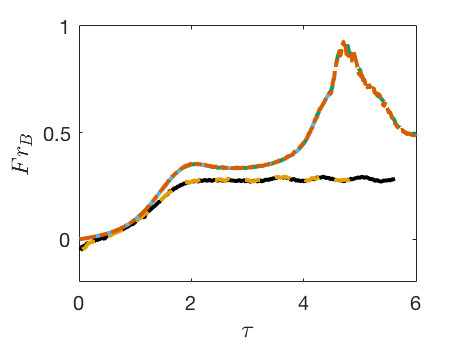

%plot for differernt Re number
%'At=0.8, DNS, 2D', 'At=0.8, LES','At=0.25, DNS','At=0.25, LES',...
% 'At=0.8, DNS, 3D', 'At=0.8, LES','At=0.25, DNS','At=0.25, LES'
if(ii==1)
    lineSty='-' ;
    lineCol=[ 0/255 0/255 0/255];
elseif(ii==2) 
    lineSty='--';
    lineCol = [ 230/255 159/255 0/255];
elseif(ii==3)
    lineSty='-' ;
    lineCol= [ 86/255 180/255 233/255];
elseif(ii==4)   
    lineSty='--';
    lineCol= [ 0/255 158/255 115/255];
elseif(ii==5)   
    lineSty='-.';
    lineCol= [ 213/255 94/255 0/255];
elseif(ii==6)   
    lineSty='-';
    lineCol= [ 204/255 121/255 167/255];
elseif(ii==7)   
    lineSty='-';
    lineCol= [240/255 226/255 66/255];
elseif(ii==8)   
    lineSty='-';
    lineCol= [ 0/255 114/255 178/255];
end
fontSize=12;
offset = 20;
len = length(t_dimless_0) - offset;
last = 10;
lineWid=2;
ratio =5;
% %KE
% figure(11)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), ke(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% xlim([0,5])
% ylabel('Kinetic energy','Interpreter','latex','fontsize',fontSize)
% if (ii== 2)
%     h=legend('at=0.04', 'at=0.8');
%     set(h,'FontSize',fontSize);
% end
% %PE
% figure(12)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), pe(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('Released potential energy','Interpreter','latex','fontsize',fontSize)
% %xlim([0,5])
% 
% %IE
% figure(13)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), ie(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('Increased internal energy','Interpreter','latex','fontsize',fontSize)
% %xlim([0,5])

% %MIX
% figure(4)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), mix_3(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('Mixing layer width','Interpreter','latex','fontsize',fontSize)
% xlim([0,8])

%ENSTROPHY
% figure(5)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), ens(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('Enstrophy','Interpreter','latex','fontsize',fontSize)
% %xlim([0,5])

%Bubble speed
figure(10)
plot(t_dimless_0(1:len), bub_vel_filter(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$Fr_B$','Interpreter','latex','fontsize',12)
xlim([0,6])

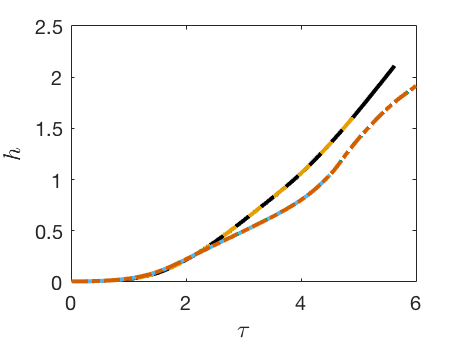

%xlim([0,5])

%Spk speed
%figure(7)
%plot(t_dimless_0(1:len), -spk_vel_filter(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
%ylabel('$Fr_S$','Interpreter','latex','fontsize',12)
%set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
%xlabel('$\tau$','Interpreter','latex','fontsize',12)
%xlim([0,8])
%ylim([-0.1,1.4])
%xlim([0,5])

% %Bubble loc
% figure(8)
% plot(t_dimless_0(1:len), bub_loc_filter(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('$h_B$','Interpreter','latex','fontsize',12)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
% xlabel('$\tau$','Interpreter','latex','fontsize',12)
% xlim([0,8])
% ylim([0.0,1.6])
% 
% %xlim([0,5])
% 
% %Spk loc
% figure(9)
% plot(t_dimless_0(1:len), -spk_loc_filter(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('$h_S$','Interpreter','latex','fontsize',12)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
% xlabel('$\tau$','Interpreter','latex','fontsize',12)
% xlim([0,8])
% ylim([0.0,1.6])
%xlim([0,5])
% 
% %mix layer
% figure(10)
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
% plot(t_dimless_0(1:len), mix_len_dimless(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
% xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',fontSize)
% ylabel('$H_{0.01}/\lambda$','Interpreter','latex','fontsize',8)
% %xlim([0,5])

figure(16)
plot(t_dimless_0(1:len), bub_loc_filter(1:len)-spk_loc_filter(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$h$','Interpreter','latex','fontsize',12)
xlim([0,6])

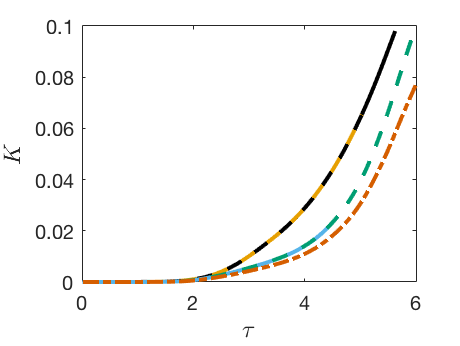


figure(17)
plot(t_dimless_0(1:len), ratio*ke(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$K$','Interpreter','latex','fontsize',12)
xlim([0,6])

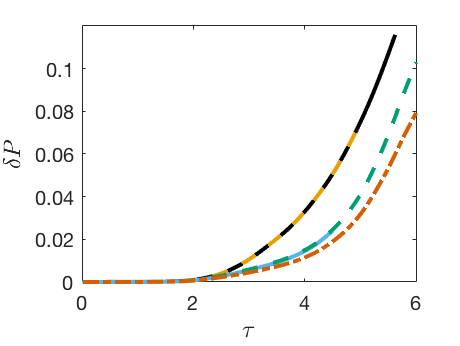


figure(18)
plot(t_dimless_0(1:len), ratio*pe(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$\delta P$','Interpreter','latex','fontsize',12)
xlim([0,6])

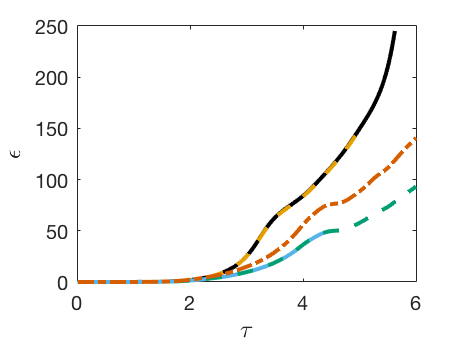


figure(19)
plot(t_dimless_0(1:len), 2*ratio*enstrophy(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$\epsilon$','Interpreter','latex','fontsize',12)
xlim([0,6])

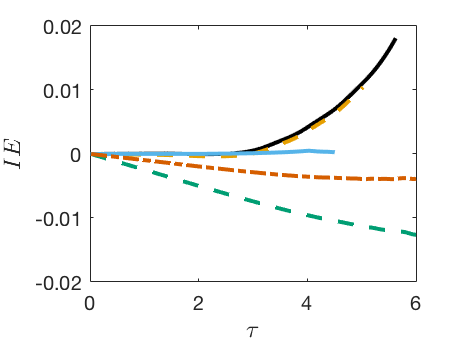


figure(29)
plot(t_dimless_0(1:len), ratio*ie(1:len), lineSty,'Color', lineCol,'LineWidth',lineWid);hold on;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
ylabel('$IE$','Interpreter','latex','fontsize',12)
xlim([0,6])




ii=ii+1;

%h=legend('Re=1000 At=0.04','Re=1000 At=0.25','Re=1000 At=0.6','Re=1000 At=0.8', 'Re=8000 At=0.8');
%set(h,'FontSize',14);


%plot for different atwood number

%plot bubble speed
set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
h=legend('$Re_p=100$','$Re_p=400$','$Re_p=1000$','$Re_p=8000$','$Re_p=20000$');
set(h,'Interpreter','latex','fontsize',9,'location','best')
legend boxoff;
xlim([0,8])
ylim([-0.1,1.25])

%%for 2d Atwood
set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
h=legend('$A=0.04$','$A=0.25$','$A=0.6$','$A=0.8$');
set(h,'Interpreter','latex','fontsize',9,'location','best')
legend boxoff;
xlim([0,8])
ylim([0,1.6])

%for 3D Re

set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
h=legend('$Re_p=210$','$Re_p=400$','$Re_p=1000$','$Re_p=8000$');
set(h,'Interpreter','latex','fontsize',9,'location','best')
legend boxoff;
xlim([0,6])
ylim([0,1.5])


%for 3D At

set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
h=legend('$Re_p=1000, A=0.04$','$Re_p=1000, A=0.25$','$Re_p=1000, A=0.6$','$Re_p=1000, A=0.8$','$Re_p=8000, A=0.04$','$Re_p=8000, A=0.8$');
set(h,'Interpreter','latex','fontsize',9,'location','best')
legend boxoff;
xlim([0,5.5])
ylim([0,5])

%for 2d omega vs. bubble speed

set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
xlabel('$\tau$','Interpreter','latex','fontsize',12)
h=legend('$Re_p=8000, A=0.04$','$Re_p=8000, A=0.6$','$Re_p=20000, A=0.04$','$Re_p=20000, A=0.6$');
set(h,'Interpreter','latex','fontsize',9,'location','best')
legend boxoff;
xlim([0,8])
ylim([0,700])


plot(t_dimless_0, bub_vel_filter, '-k','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, ':g','LineWidth',3);hold on;
plot(t_dimless_0, bub_vel_filter, '-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '-c','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '--m','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '-','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);

%plot spike speed
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$Fr_S$','Interpreter','latex','fontsize',8)
%title('Bubble and Spike speed','Interpreter','latex','fontsize',14)
%h=legend('new code','old code');
%h=legend('Re=100, Pr 1','Spk: Re 20000, Pr 1','Bub: Re 10000, Pr 1','Spk: Re 10000, Pr 1','Bub: Re 10000, Pr 10','Spk: Re 10000, Pr 10','Bub: Re 1500, Pr 1','Spk: Re 1500, Pr 1','Bub: Re 1500, Pr 10','Spk: Re 1500, Pr 10''Bub: Re 20000, Pr 10','Spk: Re 20000, Pr 10');
%legend_set(h,'FontSize',14);
%h=legend('Gr=7.9','Gr=0.99');
%h=legend('Re=100','Re=210','Re=400','Re=1000','Re=1500','Re=8000','Re=20000');
h=legend('Re=100','Re=210','Re=400','Re=1, 000','Re=1, 500','Re=8, 000','Re=20, 000');
set(h,'FontSize',8);
xlim([0,8])
ylim([-0.1,1.4])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, -spk_vel_filter, '-k','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, ':g','LineWidth',3);hold on;
plot(t_dimless_0, -spk_vel_filter, '-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '-c','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '--m','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '-','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);

%plot bubble location
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$h_B$','Interpreter','latex','fontsize',8)

h=legend('Re=100','Re=210','Re=400','Re=1, 000','Re=1, 500','Re=8, 000','Re=20, 000');
set(h,'FontSize',8);
xlim([0,8])
ylim([0,1.6])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, bub_loc_filter, '-k','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, ':g','LineWidth',3);hold on;
plot(t_dimless_0, bub_loc_filter, '-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '-c','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '--m','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '-','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);

%plot bubble location
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$h_S$','Interpreter','latex','fontsize',8)

h=legend('Re=100','Re=210','Re=400','Re=1, 000','Re=1, 500','Re=8, 000','Re=20, 000');
set(h,'FontSize',8);
xlim([0,8])
ylim([0,1.6])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, -spk_loc_filter, '-k','LineWidth',1.5);hold on; 
plot(t_dimless_0, -spk_loc_filter, '--r','LineWidth',1.5);hold on; 
plot(t_dimless_0, -spk_loc_filter, ':g','LineWidth',3);hold on; 
plot(t_dimless_0, -spk_loc_filter, '-.b','LineWidth',1.5);hold on; 
plot(t_dimless_0, -spk_loc_filter, '-c','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '--m','LineWidth',1.5);hold on; 
plot(t_dimless_0, -spk_loc_filter, '-','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);

%diff atwood
%plot bubble speed
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$Fr_B$','Interpreter','latex','fontsize',8)
h=legend('$A=0.04$','$A=0.25$','$A=0.6$','$A=0.8$');

set(h,'FontSize',8);
xlim([0,8])
ylim([0,1.7])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, bub_vel_filter, '-.k','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '.-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '-g','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '-.c','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '--m','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_vel_filter, '.-.','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);
plot(t_dimless_0, bub_vel_filter, '-','color', [ 139/255,69/255,19/255],'LineWidth',1.5);

%diff atwood
%plot spike speed
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$Fr_S$','Interpreter','latex','fontsize',8)
h=legend('Re=8, 000, A=0.04','Re=8, 000, A=0.25','Re=8, 000, A=0.6','Re=8, 000, A=0.8','Re=20, 000, A=0.04','Re=20, 000, A=0.25','Re=20, 000, A=0.6','Re=20, 000, A=0.8');

set(h,'FontSize',8);
xlim([0,8])
ylim([0,3.4])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, -spk_vel_filter, '-.k','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '.-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '-g','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '-.c','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '--m','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_vel_filter, '.-.','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);
plot(t_dimless_0, -spk_vel_filter, '-','color', [ 139/255,69/255,19/255],'LineWidth',1.5);

%diff atwood
%plot bubbl loc
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$h_B$','Interpreter','latex','fontsize',8)
h=legend('Re=8, 000, A=0.04','Re=8, 000, A=0.25','Re=8, 000, A=0.6','Re=8, 000, A=0.8','Re=20, 000, A=0.04','Re=20, 000, A=0.25','Re=20, 000, A=0.6','Re=20, 000, A=0.8');

set(h,'FontSize',8);
xlim([0,8])
ylim([0,1.6])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, bub_loc_filter, '-.k','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '.-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '-g','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '-.c','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter,'--m','LineWidth',1.5);hold on;
plot(t_dimless_0, bub_loc_filter, '.-.','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);
plot(t_dimless_0, bub_loc_filter, '-','color', [ 139/255,69/255,19/255],'LineWidth',1.5);

%diff atwood
%plot spk loc
figure;
xlabel('$t\sqrt{Ag/\lambda}$','Interpreter','latex','fontsize',8)
ylabel('$h_S$','Interpreter','latex','fontsize',8)
h=legend('Re=8, 000, A=0.04','Re=8, 000, A=0.25','Re=8, 000, A=0.6','Re=8, 000, A=0.8','Re=20, 000, A=0.04','Re=20, 000, A=0.25','Re=20, 000, A=0.6','Re=20, 000, A=0.8');
h=legend('R1, A=0.3, M=0.3','R1, A=0.3 M=1',...
    'R1, A=0.7, M=0.3','R1, A=0.7, M=1',...
   'R8, A=0.3, M=0.3','R8, A=0.3 M=1',...
    'R8, A=0.7, M=0.3','R8, A=0.7, M=1');
set(h,'FontSize',8);
set(h,'FontSize',8);
xlim([0,8])
ylim([0,1.6])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 4, 3])
plot(t_dimless_0, -spk_loc_filter, '-.k','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '--r','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '.-.b','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '-g','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '-.c','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter,'--m','LineWidth',1.5);hold on;
plot(t_dimless_0, -spk_loc_filter, '.-.','color', [ 0.9100 0.4100 0.1700],'LineWidth',1.5);
plot(t_dimless_0, -spk_loc_filter, '-','color', [ 139/255,69/255,19/255],'LineWidth',1.5);

%legend for DNS filter compare

%diff atwood
%plot bubbl loc
h=legend('$A$=0.8, DNS, nx=256', '$A=0.8$, filter, nx=128','$A$=0.04, DNS, nx=512', '$A=0.04$, filter, nx=512','$A$=0.04, filter, nx=256', '$A=0.04$, filter, nx=256', 'location','best');
set(h,'Interpreter','latex','fontsize',10)
legend boxoff;